# **Installation**

## **Introduction **

This module shows how to detect objects in images using the deep learning network you only look once version 8 (YOLO v8). 

The process has been divided into the following files:

- Installation:

- Model training:

- Post-processing

Los paquetes requeridos en este modulo son los siguientes.

**Required packages:**

- Computer Vision Toolbox™

- Deep Learning Toolbox™

- Parallel Computing Toolbox™

We add the installation module path, with this we can use the code of this folder.

addpath('installation-module');

With this code we install python and the libraries, can take more than 5 minutes.

yolo.installUltralytics();

download data


After execute this code, it should appear a *win64* in case you are using windows, else *glnxa64*.

To download the dataset: 

(It is not updated, is other dataset, don't download this)

%disp("download data")

%yolo.helper.downloadMultiClassData()

Testing YOLO is working

Loading object-detection module:

% Load YOLO v8 model
det = yolov8ObjectDetector2('yolov8s');

Pretrained yolov8s network already exists.



% Read test image.
I = imread(fullfile('data','inputTeam.jpg'));

% Load YOLO v8 small network.
det = yolov8ObjectDetector2('yolov8s');

Pretrained yolov8s network already exists.



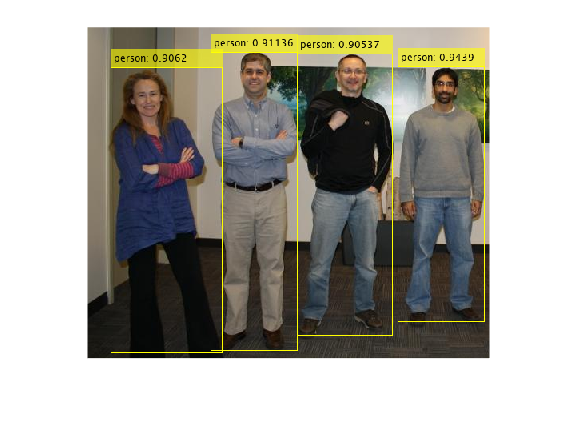


% Perform detection using pretrained model.
[bboxes, scores, labels] = detect(det, I);

% Visualize detection results.
annotations = string(labels) + ': ' + string(scores);
Iout = insertObjectAnnotation(I, 'rectangle', bboxes, annotations);
figure, imshow(Iout);

if (ispc)
    pyenv(Version="win64/python/python.exe", ExecutionMode = "OutOfProcess")
else
    pyenv(Version="glnxa64/python/bin/python3", ExecutionMode = "OutOfProcess")
end


ans =   PythonEnvironment with properties:

          Version: "3.11"
       Executable: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\win64\python\python.exe"
          Library: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\win64\python\python311.dll"
             Home: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\win64\python"
           Status: Loaded
    ExecutionMode: OutOfProcess
        ProcessID: "10932"
      ProcessName: "MATLABPyHost"


if isunix
    py.sys.setdlopenflags(int32(bitor(int64(py.os.RTLD_LAZY),int64(py.os.RTLD_DEEPBIND))));
end


% setYoloSettings Set YOLO global settings via Python wrapper.
%
% setYoloSettings(pythonObject, option, value) sets the specified YOLO
% option to the given value using the Python wrapper.
py.trainYOLOv8Wrapper.setYoloSettings(py.str('tensorboard'), true);


settings_version 0.0.4
datasets_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\datasets
weights_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\weights
runs_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\runs
uuid ec83097be249f049dc01533308f726e37a20a9a11e43afb8810c32587f8ec051
sync True
api_key 
openai_api_key 
clearml True
comet True
dvc True
hub True
mlflow True
neptune True
raytune True
tensorboard True
wandb True
True


runsDir = fullfile(pwd, 'runs'); % Une el directorio actual con la carpeta 'runs'
weightsDir = fullfile(pwd, 'weights'); % Une el directorio actual con la carpeta 'runs'
datasets_dir = fullfile(pwd, 'datasets');
py.trainYOLOv8Wrapper.setYoloSettings(py.str("runs_dir"), py.str(runsDir));
py.trainYOLOv8Wrapper.setYoloSettings(py.str("weights_dir"), py.str(weightsDir));
py.trainYOLOv8Wrapper.setYoloSettings(py.str("datasets_dir"), py.str(datasets_dir));

settings_version 0.0.4
datasets_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\datasets
weights_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\weights
runs_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\runs
uuid ec83097be249f049dc01533308f726e37a20a9a11e43afb8810c32587f8ec051
sync True
api_key 
openai_api_key 
clearml True
comet True
dvc True
hub True
mlflow True
neptune True
raytune True
tensorboard True
wandb True
True
